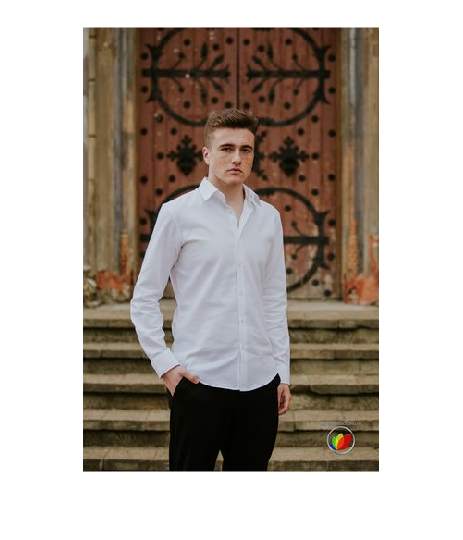

poza = imread("289472664_578150910439731_8069178649735613761_n.jpg");

imshow(poza);

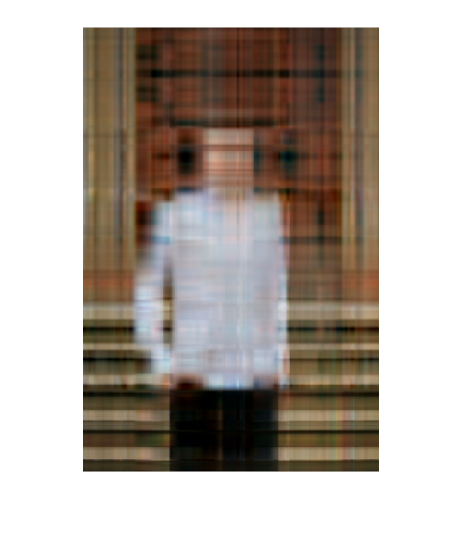


poza = im2double(poza);

R = poza(:,:,1);
G = poza(:,:,2);
B = poza(:,:,3);

[U_R, S_R, V_R] = svd(R);
[U_G, S_G, V_G] = svd(G);
[U_B, S_B, V_B] = svd(B);

k = 5;

compres_R = U_R(:,1:k) * S_R(1:k,1:k) * V_R(:,1:k)';
compres_G = U_G(:,1:k) * S_G(1:k,1:k) * V_G(:,1:k)';
compres_B = U_B(:,1:k) * S_B(1:k,1:k) * V_B(:,1:k)';

compres = cat(3, compres_R, compres_G, compres_B);

imshow(compres);


imshow(poza);